# Example 7.11: Bayesian Optimization for Closed-Loop Experimental Design

Note: this script reproduces Example 7.11 (Section 7.7) of **Statistics for Chemical Engineers**: Bayesian optimization (BO) of an extraction system, using a GP model and an acquisition function to choose each new experiment. Victor Z UW-Madison, 2020 bayesian optimization for extraction system [https://www.mathworks.com/help/stats/fitrgp.html](https://www.mathworks.com/help/stats/fitrgp.html) [https://www.mathworks.com/help/stats/compactregressiongp.predict.html](https://www.mathworks.com/help/stats/compactregressiongp.predict.html)

clc; clear all; close all hidden

% options fmincon
opt = optimoptions('fmincon','Display','iter','Algorithm','sqp');
nit = 20;

## Initial experiments

set initial database

% naive design
x=[ 0  0   0; 
   +1 +1  +1; 
   -1 -1  -1];

N=length(x);
for i=1:N
y(i)=evalobj(x(i,:));
end
y=y'

y =   -16.5780
  -18.4310
   -8.0260


## BO iterations

start bayesopt iterations

idx=find(y==min(y));
xit(1,:) = x(idx,:);
  yit(1) = evalobj(xit(1,:));
   datax = x;
   datay = y;
 
for k=1:nit

% train kriging model with available data
gprMdl = fitrgp(datax,datay,'KernelFunction','squaredexponential');

% determine new experiment
lb=-1*ones(3,1); ub=+1*ones(3,1);
xit(k+1,:) = fmincon(@acqfunc,xit(k,:),[],[],[],[],lb,ub,[],opt,gprMdl);

% evaluate new objective
  yit(k+1,1) = evalobj(xit(k+1,:));

% update database
datax=[datax; xit(k+1,:)];
datay=[datay; yit(k+1)];

end

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           4   -1.618825e+01     0.000e+00     1.000e+00     0.000e+00     9.537e-07      0.053261 sec  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

## Solution

visualize solution (scale to original units)

Xopt(1)=interp1([-1,0,1],[70 85 100],xit(nit+1,1));
Xopt(2)=interp1([-1,0,1],[1 1.5 2],xit(nit+1,2));
Xopt(3)=interp1([-1,0,1],[0.1 0.2 0.3],xit(nit+1,3));

xit=xit

xit =     1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000
    0.9817    0.9817    0.9817
    0.5440    0.5440    0.9205
    1.0000    1.0000   -0.1878
    1.0000    1.0000    0.2324
    1.0000    1.0000    0.1999
    1.0000    1.0000    0.1987
    1.0000    1.0000    0.1987
    1.0000    1.0000    0.1981
    1.0000    1.0000    0.1981
    1.0000    1.0000    0.1981
    1.0000    1.0000    0.1981
    1.0000    1.0000    0.1981
    1.0000    1.0000    0.1981


Xopt=Xopt'

Xopt =   100.0000
    2.0000
    0.2198


Yopt=yit

Yopt =   -18.4310
  -18.4310
  -18.4573
  -17.9769
  -18.9594
  -19.1253
  -19.1263
  -19.1263
  -19.1263
  -19.1263
  -19.1263
  -19.1263
  -19.1263
  -19.1263
  -19.1263


## Plots

plot results

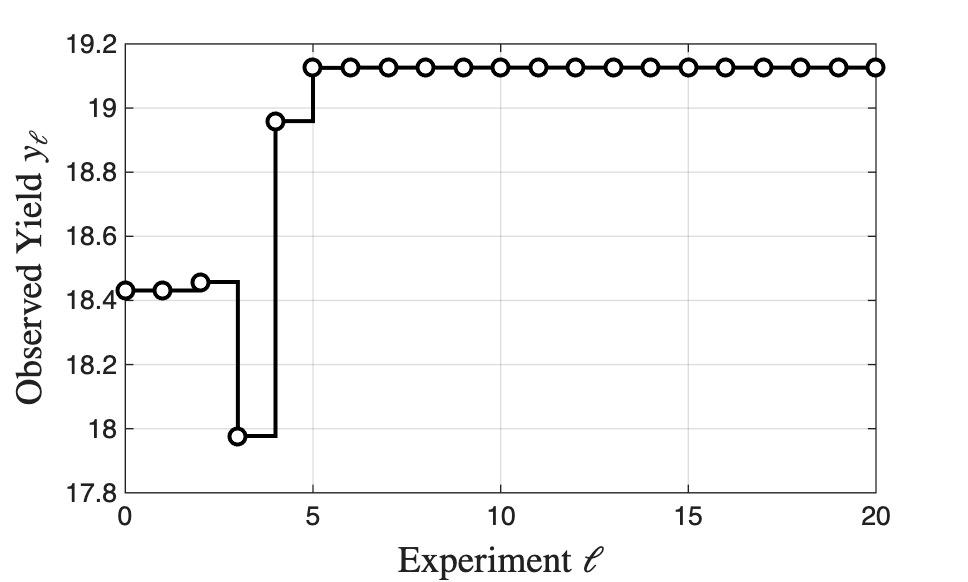

figure(1)
stairs(0:nit,-Yopt,'blacko-','MarkerFaceColor','w','LineWidth',1.5)
grid on
hold on
xlabel('$\textrm{Experiment}\; \ell$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Observed Yield}\; y_\ell$','Interpreter','latex','FontSize',14)
print -depsc ch7_bayesopt_extraction.eps

## define acquisition function

function acq=acqfunc(x,gprMdl)

[mu,~,msig] = predict(gprMdl,x);

 mu = mu;
sig = mu-msig(1);

acq = mu - 0.1*sig;

end

## define objective to optimize (unknown to BO)

function y = evalobj(x)

% extraction conditions
X1=x(1); X2=x(2); X3=x(3);

% extraction model
b=[16.5780
    3.8563
    0.9250
    0.4212
   -1.2840
   -0.8515
   -1.0940
   -0.1425
    0.1900
   -0.1675];
 
 y = b(1) + b(2)*X1   + b(3)*X2 + b(4)*X3 + b(5)*X1^2 + b(6)*X2^2+...
     b(7)*X3^2+ b(8)*X1*X2 + b(9)*X1*X3 + b(10)*X2*X3;

 y = -y;

end

## Note

As in the book, BO balances exploration and exploitation, and the experiment history converges to the best extraction conditions in a few experiments.